# A simulation of a satellite in a 500km sun synchronous orbit over a ground station using the COW protocol

## 1. Choose parameters

wavelength=780;                                                            %wavelength is measured in nm
transmitter_telescope_diameter=0.1;                                        %diameters are measured in m
orbit_data_file_location='500kmSSOrbitLLAT.txt';                              %orbits are described by files containing latitude, longitude, altitude and time stamps. These are in the 'orbit modelling resources' folder
receiver_telescope_diameter=1;                                           
time_gate_width=1E-10;                                                      %times are measured in s
spectral_filter_width=1;                                                  %consistemt with wavelength, spectral width is measured in nm
repetition_rate = 1E8;  
state_probabilities = [0.9,0.1];
mean_photon_number = 0.8;

## 2. Construct components

%2.1 Satellite
%2.1.1 Source
Transmitter_Source=components.Source(wavelength,...
                          'Repetition_Rate',repetition_rate,...
                          'Probability_Signal',state_probabilities(1),...
                          'Probability_Decoy',state_probabilities(2),...
                          'MPN_Signal',mean_photon_number);        %we use default values to simplify this example

%2.1.2 Transmitter telescope
Transmitter_Telescope=components.Telescope(transmitter_telescope_diameter);           %do not need to specify wavelength as this will be set by satellite object

%2.1.3 Construct satellite
SimSatellite=nodes.Satellite(Transmitter_Telescope,...
                        'Source',Transmitter_Source,...
                        'OrbitDataFileLocation',orbit_data_file_location);

%2.2 Ground station
%2.2.1 Detector
Generic_COW_Detector=components.Detector(wavelength,Transmitter_Source.repetition_rate,time_gate_width,spectral_filter_width,...
    'Preset','Excelitas');
%TODO: need a detector object preset with visibility
%need to provide repetition rate in order to compute QBER and loss due to
%time gating
%NOTE only detectors with the 'Visibility' property can be used for COW

%2.2.2 Receiver telescope
Receiver_Telescope=components.Telescope(receiver_telescope_diameter);

%2.2.3 construct ground station, use Heriot-Watt as an example
SimGround_Station=nodes.GroundStation(Receiver_Telescope,...
                                'Detector',Generic_COW_Detector,...
                                'LLA',[55.909723, -3.319995,10],...
                                'Name','Heriot-Watt');
%no need to set the environment. we will use the default 10km visibility

## 3 Compose and run the PassSimulation

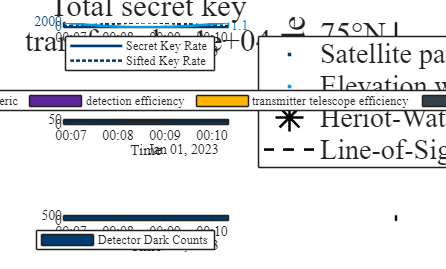

ans =   Figure (1: COW simulation from Unnamed Satellite to Heriot-Watt) with properties:

      Number: 1
        Name: 'COW simulation from Unnamed Satellite to Heriot-Watt'
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


%3.1 compose passsimulation object
Results = nodes.qkdPassSimulation(SimGround_Station,SimSatellite,protocol.COW);
%3.2 plot results
%plotResult(Results,SimGround_Station,SimSatellite);
Results.plot();